# Matrixarray

The matrixarray class is meant to simplify operations over arrays of matrices. In the Loopless_computations script the operations are vectorized using the permute, reshape, repelem and repmat functions. To streamline this process the matrixarray is used. The example below shows how the matrixarray is build. In this example we take a local matrix for each element.

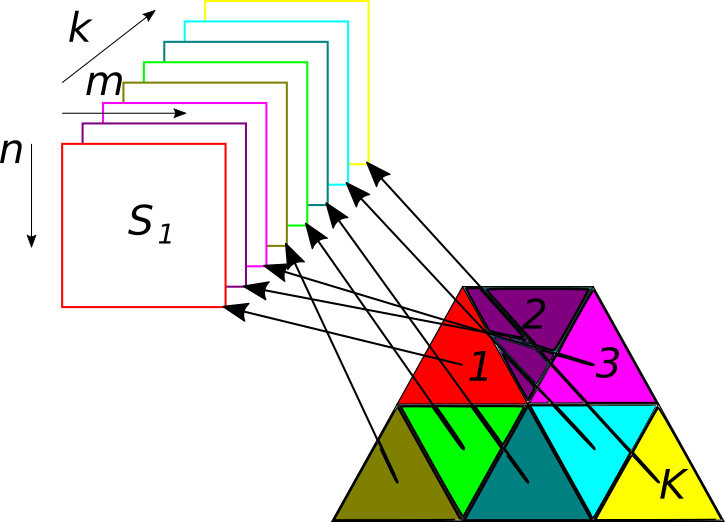

Here m and n are the size of the matrix and k corresponds to the triangles. Now if we for example want to multiply each local matrix by a material parameter differing on each element, we hit the current limits of what MATLAB's built-in routines can do.

Nd = 2;
Ne = 5;
A = kron(rand(Ne,1),rand(Nd,Nd));
B = kron(rand(Ne,1),rand(Nd,Nd));
An=permute(reshape(A,Nd,Ne,Nd),[1,3,2]);
Bn=permute(reshape(B,Nd,Ne,Nd),[3,1,2]); %transpose
I=[1 2 1 2];
J=[1 1 2 2];
Cn=dot(An(I,:,:),Bn(J,:,:),2);
Cn = reshape(Cn,Nd,Nd,Ne);
%Cn=reshape(permute(reshape(Cn,Nd,Nd,Ne),[1,3,2]),Nd*Ne,Nd);

In this example we create a set of Ne, Nd times Nd matrices. On this we then use a cumbersome and error-prone series of permute and reshape commands to be able to use the dot operation in order to perform element-wise matrix multiplications. Finally we need to reorder our result to get element-wise result matrices.

The matrixarray does exactly the same behind the scenes. 

Am = permute(reshape(A,Nd,Ne,Nd),[1,3,2]);
Bm = permute(reshape(B,Nd,Ne,Nd),[1,3,2]);
Am = ofem.matrixarray(Am);
Bm = ofem.matrixarray(Bm);
Cm = Am*Bm;

sum(sum(sum(abs(Cm-Cn))))

ans = 0

The matrixarray class allows us to treat the element wise multiplication as a simple multiplication code-wise. However, the matrixarray has to be constructed with the data in the correct order. $k$ $m \times n$ matrices. Here the order of the result stays the same as the variables.

Two illustrate the advantages of the matrixarray class we will first generate a new matrix.

A = ones(Nd,Nd,Ne)

A = A(:,:,1) =

     1     1
     1     1


A(:,:,2) =

     1     1
     1     1


A(:,:,3) =

     1     1
     1     1


A(:,:,4) =

     1     1
     1     1


A(:,:,5) =

     1     1
     1     1


Next we will store the generated data in a matrixarray.

A = ofem.matrixarray(A)

A =   2×2×5 matrixarray:

  double data:

(:,:,1) =

     1     1
     1     1


(:,:,2) =

     1     1
     1     1


(:,:,3) =

     1     1
     1     1


(:,:,4) =

     1     1
     1     1


(:,:,5) =

     1     1
     1     1


Now we have the data in the desired element-wise format. Next we will generate a set of scalar parameters to multiplicate with each individual element.

b = ones(1,1,Ne);
b = cumsum(b)

b = b(:,:,1) =

     1


b(:,:,2) =

     2


b(:,:,3) =

     3


b(:,:,4) =

     4


b(:,:,5) =

     5


Now we have the values 1 to Nd stored in b. Now we want to multiply each matrix by the corresponding entry in b. Normally we would need to repeat the elements for each matrix and inflate it to Nd x Nd format. The matrixarray handles the broadcasting for us in an efficient way.

A*b

ans =   2×2×5 matrixarray:

  double data:

(:,:,1) =

     1     1
     1     1


(:,:,2) =

     2     2
     2     2


(:,:,3) =

     3     3
     3     3


(:,:,4) =

     4     4
     4     4


(:,:,5) =

     5     5
     5     5


A+b

ans =   2×2×5 matrixarray:

  double data:

(:,:,1) =

     2     2
     2     2


(:,:,2) =

     3     3
     3     3


(:,:,3) =

     4     4
     4     4


(:,:,4) =

     5     5
     5     5


(:,:,5) =

     6     6
     6     6


Currently the following operations are supported:

- +

- -

- *

- .*

- /

- \

- reshape

- dot

- cross

- rot

- conj

- ctranspose

- transpose